# Nocodazole-induced cell blebbing and Cpd31-mediated rescue

Code related to Figure 7, panels I and J in Marshall-Burghardt et. al., 2024, Science Advances.

Written by Rodrigo Migueles Ramirez McGill University, Montreal, Canada, 2024.

## Create Big Table container

Date = {'230705'}; Treatment = {'CNTRL'}; Mean = cell(1,1); Well = 1; NofSites = 1;
BigTable = table(Date, Well, Treatment, Mean, NofSites);
BigTable(1,'Mean') = {zeros(135,1)};
index  = 1;
warning off; % Mute appending empty rows warnings

## 230705

wholeFrameArea = zeros(135, 12);
load("230705\230705-ExpSettings.mat");
load("230705\Metadata\230705-Metadata.mat");

% Get whole frame area per site
for file = ExpSettings.Selected.files_to_analyze
    for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
        fileKey = getFileKey(file, site, 0, metadata, ExpSettings.Selected.Convention);
        load([ExpSettings.MasksPath, fileKey, '-Mask.mat'], 'mask');
        wholeFrameArea(:, site) = squeeze(sum(mask, [1,2]));
        clear mask;
        disp(fileKey);
    end
end

230705-01-01-CNTRL
230705-01-02-CNTRL
230705-01-03-CNTRL
230705-01-04-NCDZL
230705-01-05-NCDZL
230705-01-06-NCDZL
230705-01-07-CPNOC
230705-01-08-CPNOC
230705-01-09-CPNOC
230705-01-10-NCRES
230705-01-11-NCRES
230705-01-12-NCRES


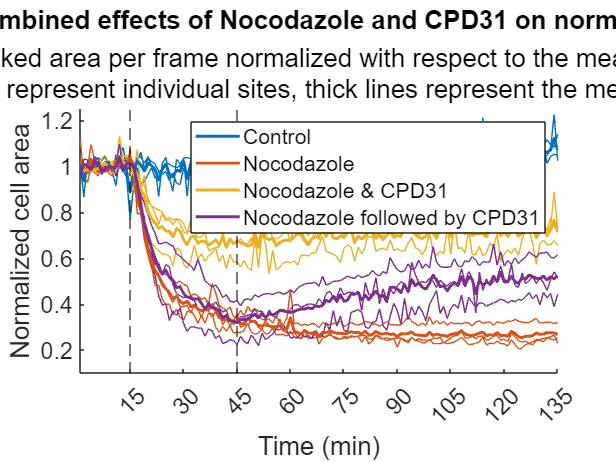

% Plot normalized cell area
fig = figure;
ax = gca; hold(ax, 'on');
cmap = lines(4);
file = 1;
for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
    well = getWellIndex(file, site, metadata);
    referenceValue = mean(wholeFrameArea(1:14, site));
    normalizedFrameArea(:, site, file) = squeeze(wholeFrameArea(:, site)./referenceValue);
    plot(normalizedFrameArea(:, site, file), 'Color', cmap(well, :), 'LineWidth', 0.5); 
end

% Store mean cell area per trial
for well = 1:4
    siteRange = reshape(1:12, [3,4])';
%     referenceValue = mean(wholeFrameArea(1:14, siteRange(well, :), file), 'all');
%     mP = plot(mean(wholeFrameArea(:, siteRange(well, :), file), 2)./referenceValue, 'Color', cmap(well, :), 'LineWidth', 2);
    mP(well) = plot(mean(normalizedFrameArea(:, siteRange(well, :), file), 2), 'Color', cmap(well, :), 'LineWidth', 2);
    BigTable(index, 'Date') = {'230705'};
    BigTable(index, 'Well') = {well};
    BigTable(index, 'Treatment') = {metadata(file).wellNames{well,1}};
    BigTable(index, 'Mean') = {mean(normalizedFrameArea(:, siteRange(well, :), file), 2)};
    BigTable(index, 'NofSites') = {size(siteRange,2)};    
    index = index +1;
end

title('Single and combined effects of Nocodazole and CPD31 on normalized cell area.');
subtitle({'Dataset: 230705. Masked area per frame normalized with respect to the mean of the first 14 frames.';...
    'Thin lines represent individual sites, thick lines represent the mean of them.'});
ax.YLabel.String = 'Normalized cell area';
ax.XLabel.String = 'Time (min)';
xline(15, '--k');
xline(45, '--k');
ax.FontSize = 16;
xlim([1,135]);
ylim([0.1, 1.25]);
xticks([15:15:135]);
legend(mP(1:4), {'Control', 'Nocodazole', 'Nocodazole & CPD31', 'Nocodazole followed by CPD31'});
fig.WindowState = 'maximized';

## 230922

load("230922\Metadata\230922-Metadata.mat");
load("230922\230922-ExpSettings.mat");

wholeFrameArea = zeros(180, 12);

% Get whole frame area per site
for file = ExpSettings.Selected.files_to_analyze
    for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
        fileKey = getFileKey(file, site, 0, metadata, ExpSettings.Selected.Convention);
        load([ExpSettings.MasksPath, fileKey, '-Mask.mat'], 'mask');
        wholeFrameArea(:, site) = squeeze(sum(mask, [1,2]));
        clear mask;
        disp(fileKey);
    end
end

230922-01-01-CNTRL
230922-01-02-CNTRL
230922-01-03-CNTRL
230922-01-04-NCDZL
230922-01-05-NCDZL
230922-01-06-NCDZL
230922-01-07-CPNOC
230922-01-08-CPNOC
230922-01-09-CPNOC
230922-01-10-NCRES
230922-01-11-NCRES
230922-01-12-NCRES
230922-01-13-CPD31
230922-01-14-CPD31
230922-01-15-CPD31



% Plot normalized cell area
fig = figure;
ax = gca; hold(ax, 'on');
cmap = lines(5);
file = 1;
for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
    well = getWellIndex(file, site, metadata);
    if strcmpi(metadata(file).wellNames{well,1}, 'CPD31')
        continue
    end
    referenceValue = mean(wholeFrameArea(15:29, site));
    normalizedFrameArea(:, site, file) = squeeze(wholeFrameArea(15:149, site)./referenceValue);
    plot(normalizedFrameArea(:, site, file), 'Color', cmap(well, :), 'LineWidth', 0.5); 
end

% Store mean cell area per trial
for well = 1:5
    siteRange = reshape(1:15, [3,5])';
%     referenceValue = mean(wholeFrameArea(1:14, siteRange(well, :), file), 'all');
%     mP = plot(mean(wholeFrameArea(:, siteRange(well, :), file), 2)./referenceValue, 'Color', cmap(well, :), 'LineWidth', 2);
    if strcmpi(metadata(file).wellNames{well,1}, 'CPD31')
        continue
    end
    mP(well) = plot(mean(normalizedFrameArea(:, siteRange(well, :), file), 2), 'Color', cmap(well, :), 'LineWidth', 2);
    BigTable(index, 'Date') = {'230922'};
    BigTable(index, 'Well') = {well};
    BigTable(index, 'Treatment') = {metadata(file).wellNames{well,1}};
    BigTable(index, 'Mean') = {mean(normalizedFrameArea(:, siteRange(well, :), file), 2)};
    BigTable(index, 'NofSites') = {size(siteRange,2)};    
    index = index +1;
end

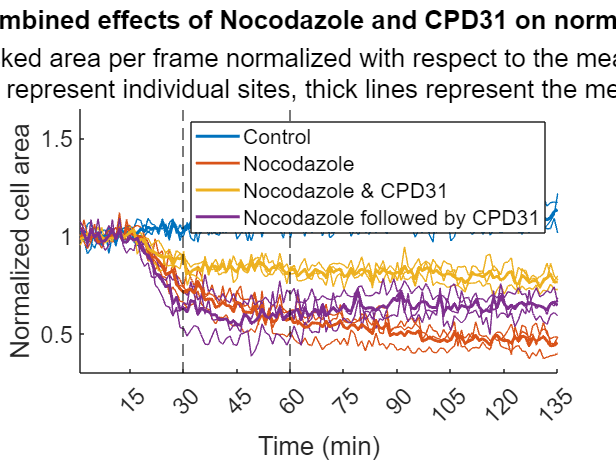


% Visualization 
title('Single and combined effects of Nocodazole and CPD31 on normalized cell area.');
subtitle({'Dataset: 230922. Masked area per frame normalized with respect to the mean of the first 14 frames.';...
    'Thin lines represent individual sites, thick lines represent the mean of them.'});
ax.YLabel.String = 'Normalized cell area';
ax.XLabel.String = 'Time (min)';
xline(30, '--k');
xline(60, '--k');
legend(mP(1:4), {'Control', 'Nocodazole', 'Nocodazole & CPD31', 'Nocodazole followed by CPD31'});
ax.FontSize = 16;
xlim([1,135]);
ylim([0.3, 1.65]);
xticks([15:15:180]);
fig.WindowState = 'maximized';

## 230921

load("230921\230921-ExpSettings.mat");
load("230921\Metadata\230921-Metadata.mat");

wholeFrameArea = zeros(135, 12);
frameRange = {NaN; 1:90; 91:135};

for file = ExpSettings.Selected.files_to_analyze
    for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
        fileKey = getFileKey(file, site, 0, metadata, ExpSettings.Selected.Convention);
        load([ExpSettings.MasksPath, fileKey, '-Mask.mat'], 'mask');
        wholeFrameArea(frameRange{file}, site) = squeeze(sum(mask, [1,2]));
        clear mask;
        disp(fileKey);
    end
end

230921-02-NC-01-CNTRL
230921-02-NC-02-CNTRL
230921-02-NC-03-CNTRL
230921-02-NC-04-CNTRL
230921-02-NC-05-NCDZL
230921-02-NC-06-NCDZL
230921-02-NC-07-NCDZL
230921-02-NC-08-NCDZL
230921-02-NC-09-CPNOC
230921-02-NC-10-CPNOC
230921-02-NC-11-CPNOC
230921-02-NC-12-CPNOC
230921-02-NC-13-NCRES
230921-02-NC-14-NCRES
230921-02-NC-15-NCRES
230921-02-NC-16-NCRES
230921-03-NR-01-CNTRL
230921-03-NR-02-CNTRL
230921-03-NR-03-CNTRL
230921-03-NR-04-CNTRL
230921-03-NR-05-NCDZL
230921-03-NR-06-NCDZL
230921-03-NR-07-NCDZL
230921-03-NR-08-NCDZL
230921-03-NR-09-CPNOC
230921-03-NR-10-CPNOC
230921-03-NR-11-CPNOC
230921-03-NR-12-CPNOC
230921-03-NR-13-NCRES
230921-03-NR-14-NCRES
230921-03-NR-15-NCRES
230921-03-NR-16-NCRES


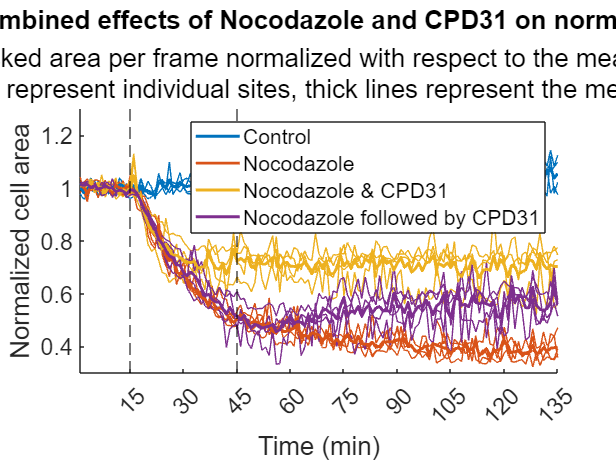


fig = figure;
ax = gca; hold(ax, 'on');
cmap = lines(4);
file = 2;
for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
    well = getWellIndex(file, site, metadata);
    referenceValue = mean(wholeFrameArea(1:14, site));
    normalizedFrameArea(:, site, file) = squeeze(wholeFrameArea(:, site)./referenceValue);
    plot(normalizedFrameArea(:, site, file), 'Color', cmap(well, :), 'LineWidth', 0.5); 
end

for well = 1:4
    siteRange = reshape([1:16], [4,4])';
%     referenceValue = mean(wholeFrameArea(1:14, siteRange(well, :), file), 'all');
%     mP = plot(mean(wholeFrameArea(:, siteRange(well, :), file), 2)./referenceValue, 'Color', cmap(well, :), 'LineWidth', 2);
    mP(well) = plot(mean(normalizedFrameArea(:, siteRange(well, :), file), 2), 'Color', cmap(well, :), 'LineWidth', 2);
    BigTable(index, 'Date') = {'230921'};
    BigTable(index, 'Well') = {well};
    BigTable(index, 'Treatment') = {metadata(file).wellNames{well,1}};
    BigTable(index, 'Mean') = {mean(normalizedFrameArea(:, siteRange(well, :), file), 2)};
    BigTable(index, 'NofSites') = {size(siteRange,2)};
    index = index +1;
end

title('Single and combined effects of Nocodazole and CPD31 on normalized cell area.');
subtitle({'Dataset: 230921. Masked area per frame normalized with respect to the mean of the first 14 frames.';...
    'Thin lines represent individual sites, thick lines represent the mean of them.'});
ax.YLabel.String = 'Normalized cell area';
ax.XLabel.String = 'Time (min)';
xline(15, '--k');
xline(45, '--k');
legend(mP(1:4), {'Control', 'Nocodazole', 'Nocodazole & CPD31', 'Nocodazole followed by CPD31'});
ax.FontSize = 16;
xlim([1,135]);
ylim([0.3, 1.3]);
xticks([15:15:135]);
fig.WindowState = 'maximized';

## 231018

load("231018\231018-ExpSettings.mat");
load("231018\Metadata\231018-Metadata.mat");

wholeFrameArea = zeros(135, 16);
frameRange = {1:90; 91:135};

for file = ExpSettings.Selected.files_to_analyze
    for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
        fileKey = getFileKey(file, site, 0, metadata, ExpSettings.Selected.Convention);
        load([ExpSettings.MasksPath, fileKey, '-Mask.mat'], 'mask');
        wholeFrameArea(frameRange{file}, site) = squeeze(sum(mask, [1,2]));
        clear mask;
        disp(fileKey);
    end
end

231018-01-01-CNTRL
231018-01-02-CNTRL
231018-01-03-CNTRL
231018-01-04-CNTRL
231018-01-05-NCDZL
231018-01-06-NCDZL
231018-01-07-NCDZL
231018-01-09-CPNOC
231018-01-10-CPNOC
231018-01-11-CPNOC
231018-01-12-CPNOC
231018-01-13-NCRES
231018-01-14-NCRES
231018-01-15-NCRES
231018-01-16-NCRES
231018-02-01-CNTRL
231018-02-02-CNTRL
231018-02-03-CNTRL
231018-02-04-CNTRL
231018-02-05-NCDZL
231018-02-06-NCDZL
231018-02-07-NCDZL
231018-02-08-NCDZL
231018-02-09-CPNOC
231018-02-10-CPNOC
231018-02-11-CPNOC
231018-02-12-CPNOC
231018-02-13-NCRES
231018-02-14-NCRES
231018-02-15-NCRES
231018-02-16-NCRES


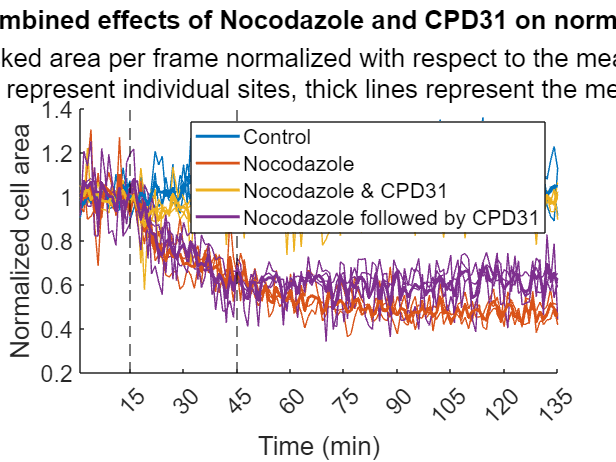


wholeFrameArea(wholeFrameArea == 0) = NaN;
wholeFrameArea(16,1) = NaN;

fig = figure;
ax = gca; hold(ax, 'on');
cmap = lines(4);
file = 2;
for site = ExpSettings.Selected.sites(file, 1:ExpSettings.Selected.n_sites_per_file(file))
    well = getWellIndex(file, site, metadata);
    referenceValue = mean(wholeFrameArea(1:14, site));
    normalizedFrameArea(:, site, file) = squeeze(wholeFrameArea(:, site)./referenceValue);
    plot(normalizedFrameArea(:, site, file), 'Color', cmap(well, :), 'LineWidth', 0.5); 
end

normalizedFrameArea(16,1,2) = NaN;
normalizedFrameArea(:,8,2) = NaN;

for well = 1:4
    siteRange = reshape(1:16, [4,4])';
%     referenceValue = mean(wholeFrameArea(1:14, siteRange(well, :), file), 'all');
%     mP = plot(mean(wholeFrameArea(:, siteRange(well, :), file), 2)./referenceValue, 'Color', cmap(well, :), 'LineWidth', 2);
    mP(well) = plot(mean(normalizedFrameArea(:, siteRange(well, :), file), 2, 'omitnan'), 'Color', cmap(well, :), 'LineWidth', 2);
    BigTable(index, 'Date') = {'231018'};
    BigTable(index, 'Well') = {well};
    BigTable(index, 'Treatment') = {metadata(file).wellNames{well,1}};
    BigTable(index, 'Mean') = {mean(normalizedFrameArea(:, siteRange(well, :), file), 2, 'omitnan')};
    BigTable(index, 'NofSites') = {size(siteRange,2)};
    index = index +1;
end

title('Single and combined effects of Nocodazole and CPD31 on normalized cell area.');
subtitle({'Dataset: 231018. Masked area per frame normalized with respect to the mean of the first 14 frames.';...
    'Thin lines represent individual sites, thick lines represent the mean of them.'});
ax.YLabel.String = 'Normalized cell area';
ax.XLabel.String = 'Time (min)';
xline(15, '--k');
xline(45, '--k');
legend(mP(1:4), {'Control', 'Nocodazole', 'Nocodazole & CPD31', 'Nocodazole followed by CPD31'});
ax.FontSize = 16;
xlim([1,135]);
% ylim([0.3, 1.3]);
xticks([15:15:135]);
fig.WindowState = 'maximized';

## Combine the 4 datasets

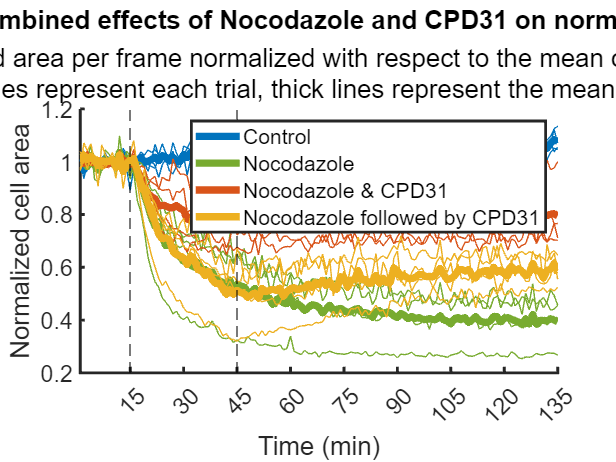

conditions = categories(categorical(BigTable.Treatment));
conditions{2} = conditions{3};
conditions{3} = 'CPNOC';

fig = figure;
ax = gca; hold(ax, 'on');

% cmap = lines(5);
% cmap = [0           0.4470    0.7410;
%             0.4700    0.6700    0.1900;
%             0.8500    0.3250    0.0980;
%             0.4940    0.1840    0.5560];

cmap = [0.00,0.45,0.74;
            0.47,0.67,0.19;
            0.85,0.33,0.10;
            0.93,0.69,0.13];

index = 1;
for c = 1:4
    
    condition = conditions{c,1};
    dataTable = BigTable(strcmpi(BigTable.Treatment, condition), 'Mean');
    
    for d = 1:4
        dataMean = table2array(dataTable(d, 'Mean'));
        allDates(1:135, d) = dataMean{1,1};
        plot(dataMean{1,1}, 'Color', cmap(index, :), 'LineWidth', 0.25, 'LineStyle', '-');
    end
    
    meanPlots(c) = plot(mean(allDates, 2), 'Color', cmap(index, :), 'LineWidth', 5);
    
    index = index + 1;
end

title('Single and combined effects of Nocodazole and CPD31 on normalized cell area.');
subtitle({'Four independent trials. Masked area per frame normalized with respect to the mean of the 14 frames before treatment.';...
    'Dotted lines represent each trial, thick lines represent the mean of all trials.'});
ax.YLabel.String = 'Normalized cell area';
ax.XLabel.String = 'Time (min)';
xline(15, '--k');
xline(45, '--k');
lg = legend(meanPlots, {'Control', 'Nocodazole',...
    'Nocodazole & CPD31', 'Nocodazole followed by CPD31'});

ax.FontSize = 16;
xlim([1,135]);
ylim([0.2, 1.2]);
xticks([15:15:135]);
fig.WindowState = 'maximized';
ax.LineWidth = 2;

## Fig. 7J - Create Table with the last data point of the mean of each trial

Treatment = {'CNTRL'}; Date = {'230705'}; LastMeanValue = 0;
lastPointTable = table(Treatment, Date, LastMeanValue);

conditions = categories(categorical(BigTable.Treatment));
conditions{2} = conditions{3};
conditions{3} = 'CPNOC';

dateNames = categories(categorical(BigTable.Date));

index = 1;
for c = 1:4
    condition = conditions{c,1};
    for d = 1:4
        dateName = dateNames{d};
        lastPointTable(index, 'Treatment') = {condition}; 
        lastPointTable(index, 'Date') = {dateName};
        TempMeans = table2array(BigTable(strcmpi(dateName, BigTable.Date) & strcmpi(condition, BigTable.Treatment), 'Mean'));
        TempMeansArray = vect(TempMeans{1,1});
        lastPointTable(strcmpi(lastPointTable.Treatment, condition) & strcmpi(lastPointTable.Date, dateName), 'LastMeanValue') = {TempMeansArray(end,1)};
        index = index + 1;
    end
end
lastPointTable

lastPointTable = 16×3 table
    Treatment       Date       LastMeanValue
    _________    __________    _____________

    {'CNTRL'}    {'230705'}        1.0711   
    {'CNTRL'}    {'230921'}        1.0549   
    {'CNTRL'}    {'230922'}        1.1346   
    {'CNTRL'}    {'231018'}        1.0467   
    {'NCDZL'}    {'230705'}       0.26702   
    {'NCDZL'}    {'230921'}       0.39802   
    {'NCDZL'}    {'230922'}       0.45571   
    {'NCDZL'}    {'231018'}       0.45646   
    {'CPNOC'}    {'230705'}       0.71166   
    {'CPNOC'}    {'230921'}       0.70267   
    {'CPNOC'}    {'230922'}       0.76589   
    {'CPNOC'}    {'231018'}        1.0001   
    {'NCRES'}    {'230705'}       0.52388   
    {'NCRES'}    {'230921'}       0.55503   
    {'NCRES'}    {'230922'}       0.64569   
    {'NCRES'}    {'231018'}       0.58886   


save('MainFigures\Fig7\Fig 7 F, H-J\Results\Fig 7J - Lat time point area\CellAreaNocRescueLastMeanPoint.mat', "lastPointTable");
writetable(lastPointTable, 'MainFigures\Fig7\Fig 7 F, H-J\Results\Fig 7J - Lat time point area\CellAreaNocRescueLastMeanPoint.xlsx');
warning on;